# Kernel Ridge Regression Example

Robert Kuramshin

This is a walkthrough example of how to use a kernel ridge regression (KRR) method in Matlab. This specific example attempts to model a function (with added gaussian noise) in $R^3$ space using the gaussian kernel trick. THis example can be expanded to data with higher dimensionality. 

### Process Inputs

Import and normalize data

clear all;clc;

data=zscore(csvread('gaussian_data.csv'));

x=data(:,1:end-1);
y=data(:,end);

Randomly shuffle samples

N = length(y);

shuffled_indexes = randperm(N);

x = x(shuffled_indexes,:);
y = y(shuffled_indexes,:);

Create a test/train split

t_split = 0.6;

N_train = N*t_split;
N_test = N-N_train;

x_test = x(N_train+1:end,:);
x_train = x(1:N_train,:);

y_test = y(N_train+1:end,:);
y_train = y(1:N_train,:);

### Create Model

Create a 2D gaussian kernel that will represent the multidimensional data. This kernel will be based on the train sample data $x$ and $y$. The following is the kernel formula:


$$K_{i,j} =\mathrm{exp}\left(-\left\|x_j -x_i \right\|\right)$$


K=zeros(N_train,N_train);
for j=1:N_train
 for i=1:N_train
    K(i,j)=exp(-norm(x_train(j,:)-x_train(i,:)));
 end
end

Apply the kernel to the test data. This is done using the ridge regression formula:


$$\hat y = y^T (K + \lambda I)^{-1} K$$


Notice that in the code we keep $\lambda$ constant. $\lambda$ is a hyperparameter that is normaly tunned to achieve higher accuracy. A higher value of $\lambda$ signifies that we trust our data less and helps counter overfitting.

y_predicted_sample=zeros(N_train,1);

lambda=0.1;

for i=1:N_train
    if mod(i,10) == 0
        fprintf('Training on Sample: %d of %d\n',i,N_train);
    end
    y_predicted_sample(i,1)= y_train'*((K+ lambda*eye(N_train))\K(i,:)');
end

Training on Sample: 10 of 120
Training on Sample: 20 of 120
Training on Sample: 30 of 120
Training on Sample: 40 of 120
Training on Sample: 50 of 120
Training on Sample: 60 of 120
Training on Sample: 70 of 120
Training on Sample: 80 of 120
Training on Sample: 90 of 120
Training on Sample: 100 of 120
Training on Sample: 110 of 120
Training on Sample: 120 of 120



in_sample_error = norm(y_predicted_sample-y_train)^2/N_train

in_sample_error = 0.0241

The resulting fit should be good, as we are testing our model against the same data it was trained on

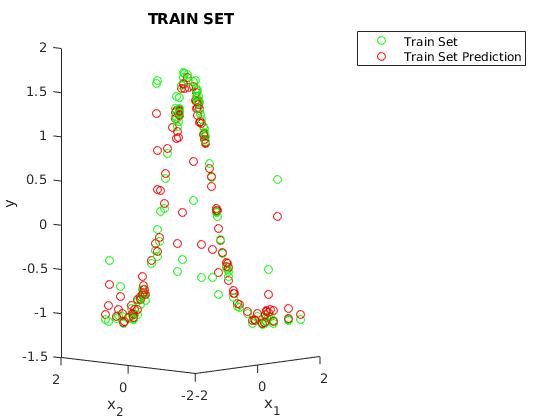

figure
hold on

scatter3(x_train(:,1),x_train(:,2),y_train,'g')
scatter3(x_train(:,1),x_train(:,2),y_predicted_sample,'r')

title('TRAIN SET')
xlabel({'x_1'})
ylabel({'x_2'})
zlabel('y')
view([-47.1 4.4])
legend('Train Set','Train Set Prediction')

hold off

### Testing Model

Now, we can use the kernel we created in the previous step and apply it to a novel $x\prime$ and $y\prime$. The following equations outline how we will make a prediction:


$$k_{i,j} =\mathrm{exp}\left(-\left\|x_i -{x_j }^{\prime } \right\|\right)$$



$$\hat y^\prime = y^T (K + \lambda I)^{-1} \kappa$$


k=zeros(N_test,N_train);
for j=1:N_train
 for i=1:N_test
    k(i,j)=exp(-norm(x_train(j,:)-x_test(i,:)));
 end
end

y_predicted=zeros(N_test,1);

for i=1:N_test
    y_predicted(i,1)= y_train'*((K+ lambda*eye(N_train))\k(i,:)');
end

out_sample_error = norm(y_predicted-y_test)^2/N_test

This new visualization shows the predicted $\hat y^{\prime }$ compared to $y^{\prime }$. This is infinately more significant than the original plot as these $\hat y^{\prime }$ values were obtained with no knowledge of the corresponding $y^{\prime }$ values. 

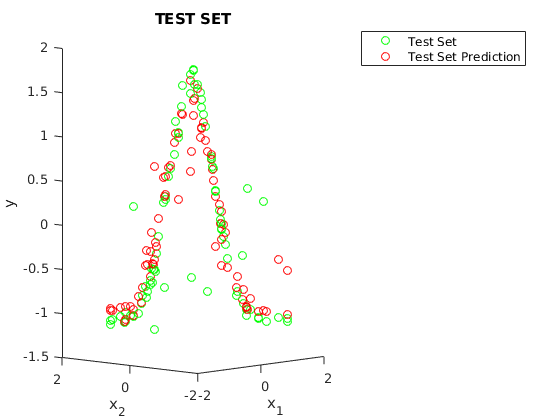

figure
hold on

scatter3(x_test(:,1),x_test(:,2),y_test,'g')
scatter3(x_test(:,1),x_test(:,2),y_predicted,'r')

title('TEST SET')
xlabel({'x_1'})
ylabel({'x_2'})
zlabel('y')
view([-47.1 4.4])
legend('Test Set','Test Set Prediction')

hold off

#### Robert Kuramshin